# Hyperparameters in GUM

### Types of hyperparameters

Hyperparameters are variables in the regression model that are fixed (and so, unlike regression weights, are not estimated during the inference process). In GUMs there are two types of hyperparameters:

- *covariance hyperparameters*, i.e. hyperparameters that determine the prior over some set of weights, or more specifically over the prior covariance. For example, for linear and categorical regressors, i.e. `'y~x'` or `'y~cat(x)'`, there is one hyperparameter controlling the variance of the weight prior. This is also the case for nonlinear mapping using basis functions, i.e. polynomial as in `'y~poly5(x)'`, where the prior is defined on the weight of each basis function. For nonlinear mapping using the Gaussian Prior (or periodic covariance for periodic functions), e.g. `'y~f(x)', `there are two hyperparameters: one that controls the variance of the prior, while the other controls the scale of the kernel (the larger the scale, the smoother the function is expected to be).

- *basis functions hyperparameters*, that control the set of basis functions used to capture the nonlinear mapping of a function (see details in the [tutorial on nonlinear mapping](matlab:open('./tutorial3_nonlinear_mapping.mlx'))). For example, for exponential basis funcions as in `'y~exp3(x)'`, there are 3 hyperparameters $\tau_1,\tau_2,\tau_3$ that each control the time constant for an exponential basis function $b_k(x)=\exp(-x/\tau_k)$. Note that some set of basis functions like polynomials and fourier components are fixed and thus do not take any hyperparameter.

### Defining hyperparameters

Each hyperparameter is automatically assigned a "reasonable" value when creating a gum, but you can set up the value of your choice for each hyperparameter by adding optional argument to the formula:

- the variance hyperparameter $\alpha$ can be set using the `variance` label, i.e. `cat(x;variance=10)` for a categorical regressor, x(variance=100) for a linear regressor, `f(x; variance=2)` for nonlinear mapping (with GP framework)`, `poly3(x; variance=6) for nonlinear mapping with polynomial basis functions

- the scale hyperparameter for nonlinear mapping can be set using the `scale` label, i.e. `f(x;scale=10).` If your model includes a function of two or more variables, set the scale parameter for each variable separated by comas, e.g. `f(x,y;scale=1,10)` to use a scale of 1 along variable $x$ and of 10 along variable $y$. ALternatively, you can use a common scale for all variables by using the `singlescale` label, e.g. `f(x,y;singlescale=true;scale=10)`.

- the scale hyperparameter for exponential basis functions can be defined using the `tau` label, i.e. `exp(x;tau=3)` to define a single basis function as $b_1(x)=\exp(-x/3)$, and `exp3(x;tau=1,3,5)` to define 3 basis functions with $\tau_1=1$,$\tau_2=3$ and $\tau_3=5$.

- likewise, you can set the hyperparameters for the raised-cosine basis functions using labels `a`, `c` and `Phi.`

### Reading hyperparameters

You can access information about hyperparameters in a model using the `get_hyperparameter_structure `method. `M.get_hyperparameter_structure() `will provide an array of structure, where each structure provides information about the hyperparameters related to a set of weights. To access the hyperparameters related a specific set of weights, use `M.get_hyperparameter_structure(lbl) ` where `lbl `is the label for these weights. See example below.

% load the same dataset of monkey performing discrimination task
T = load_online_dataset();

loading csv file from url...done


% define model of choice depending on current stimulus and previous
% responses (with a set of two exponential basis functions)
M= gum(T, 'resp ~ Stimulus + lag(response;Lags=1:20;basis=exp2)');

M.get_hyperparameter_structure("response")

ans = struct with fields:
       HP: [0 2.9444 0]
    label: ["log \tau1"    "log \tau2"    "log \lambda"]
      fit: [1 1 1]
       LB: [-2 -2 -12]
       UB: [7.9444 7.9444 12]
    index: []
     type: ["basis"    "basis"    "cov"]


The structure provides the value of the hyperparameters (you will see they are often defined in log-space), their labels, whether they should be fitted or not as well as lower and upper bounds (see below), and their type ("`basis`" if they define basis functions, "`cov`" if they define prior covariance).

### Fitting hyperparameters

When estimating model parameter weights using `M.infer()` the hyperparameters are fixed. But you can also fit the hyperparameters to the data as in Empirical Bayes using `M.fit()`. More precisely, `fit` will first fit the hyperparameters to the data and then estimate the model weights (approximate the posterior over weights) for the fitted value of the value of the hyperparameters.

So basically you can fit the hyperparameters and then plot the resulting set of weights following:

M = M.fit(); % we're fitting the hyperparameters of the model we defined above

Initial weight inference (10 starting points):*
HP fitting: iter 1, log evidence -29535.433824
HP fitting: iter 2, log evidence -29516.883690
HP fitting: iter 3, log evidence -29516.883656


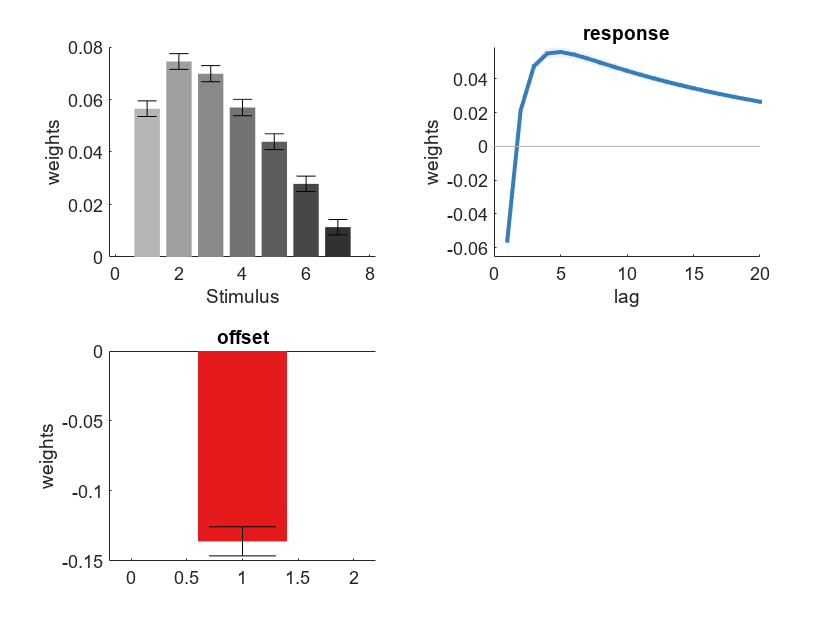

figure;
M.plot_weights;

#### Fitting methods

There are three different methods for fitting hyperparameters, which you can specify by the call `M.fit('algo',method)` where method can be:

- `'EM'`: Expectation-Maximization algorithm, which iteratively maximizes the marginal evidence of the model given by the Laplace approximation. This is the default method when calling `M.fit()`. This method works very well in general, with the marginal evidence increasing after each iteration, although it may be slow to converge. It can struggle also when fitting hyperparameters for basis functions (because the posterior covariance is not full rank in the original space), which you will notice if the marginal evidence starts decreasing. In this case it is probably more appropriate to use the alternative fitting procedure (see below).

- `'cv'`: cross-validation, which maximizes the log-likelihood of the model on a subset of the dataset (test set), with the weights corresponding to the posterior mean inferred on a different subset of the dataset (training set). This cross-validated log-likelihood is summed over different folds where different subsets of the dataset are taken as the test set. You can define the training and test sets using `M.fit('algo',cv','crossvalidation',C)` . `C `can either be a cross-validation partition created by `cvpartition` (from the stats toolbox); a cell array of two columns with the cells in the first column defining the indices of observation in the training sets and cells in the second column defining the indices of observations in the test sets (the number of rows corresponds to the number of folds); an integer defining the number of observations in each training set; or a scalar between 0 and 1 defining the proportion of observations in each training set. For the latter two cases, the number of folds is set to 10 by default, but can be adjusted by calling `M.fit('algo',cv','crossvalidation',C,'nFold',n). `By default, fitting is done using gradient-based optimization where the gradient of the cross-validated log-likelihood is computed automatically. You can turn off this behavior by calling `M.fit(...,'gradient','off')`. 

- `'basic'` (not recommended): directly maximizes the approximated marginal evidence.

Note also that both methods will provide hyperparameters which are local optima of their respective metric (marginal evidence or cross-validated log-likelihood) but are not guaranteed to be global optima.

**Additional options**: 

- `M.fit(...,'maxiter',nIter)` where `nIter` is an integer defines the maximum number of iterations for hyperparameter optimization (default: 200)

- `M.fit(...,'maxiter',`TolFun`)` where TolFun is a scalar defined the tolerance criterion for stopping optimization (default: 0.001)

- `M.fit(...,'verbose',str) `controls the output of fitting on the command line. Possible values for `str` are  '`full`', '`on`' [default for 'em'], '`off`' and '`iter`' [default for other methods].

#### Specifying which hyperparameters to fit

By default, all hyperparameters will be fitted when calling the method `fit`. In practice, this can lead to a large multidimensional space while can complicate the fitting. Oftentimes we expect many hyperparameters to play only a marginal role as long as they take "reasonable" values, or simply we want some hyperparameters to stay fixed. GUM lets you decide which hyperparameters to fit when declaring the formula, by using the `fit` label for each regressor - e.g. `f(x;fit=value)`:

- `fit=all` will define all hyperparameters correponding to this regressor as fittable. This is the default behavior.

- `fit=none `will define all hyperparameters correponding to this regressor as fixed.

- `fit=variance `sets the variance hyperparameter as the only fittable hyperparameter for the corresponding regressor

- `fit=scale` (for nonlinear mapping) sets the scale hyperparameter as the only fittable hyperparameter.

### Plotting hyperparameters

You can easily plot the hyperparameters of a model (either prior to fitting or after fitting them) using the `plot_hyperparameters `method:

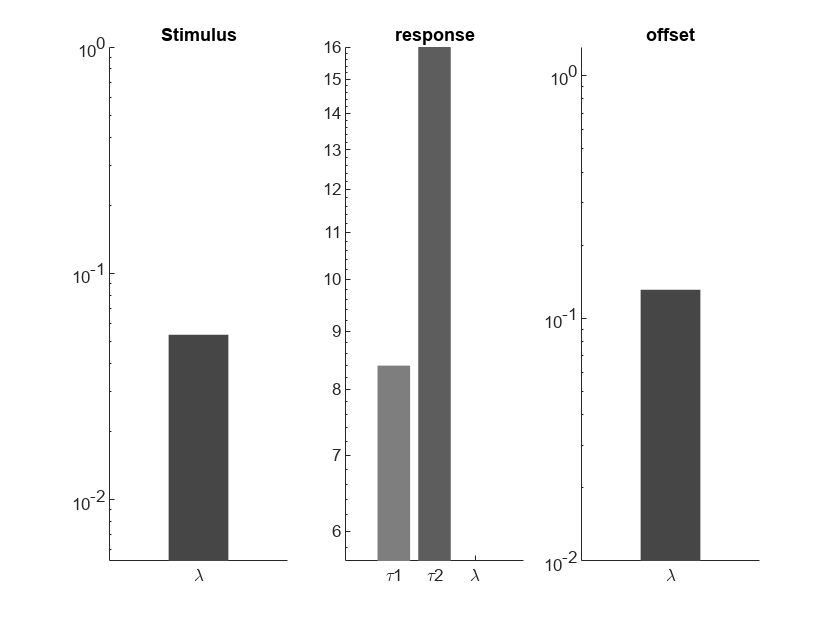

figure;
M.plot_hyperparameters;

**Next tutorial: **In the [next tutorial](matlab:open('./tutorial7_model_validation_and_model_selection.mlx')) we will see how we can validate a model, simulate a model, diagnostic tools and how to compare different models.